%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Global Threshold           %
% Global Histogram Threshold %
% Multilevel Threshold       %                             
% Adaptive Image Threshold   %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Global Threshold
%%%%%%%%%%%%%%%%%%%%%

%Read a grayscale image into the workspace.
%load('IM_00039_1.plq','-mat');
%load('IM_00039_2.plq','-mat');
%load('IM_00039_3.plq','-mat');
I = imread('IM_00039.TIF');
%I = dicomread('img1722-221.5.dcm')
%figure, imshow(I), hold on, plot(yi,xi, 'LineWidth', 3), hold off;


%Calculate a threshold using graythresh. The threshold is normalized to the range [0, 1].
level = graythresh(I)

level = 0.2275

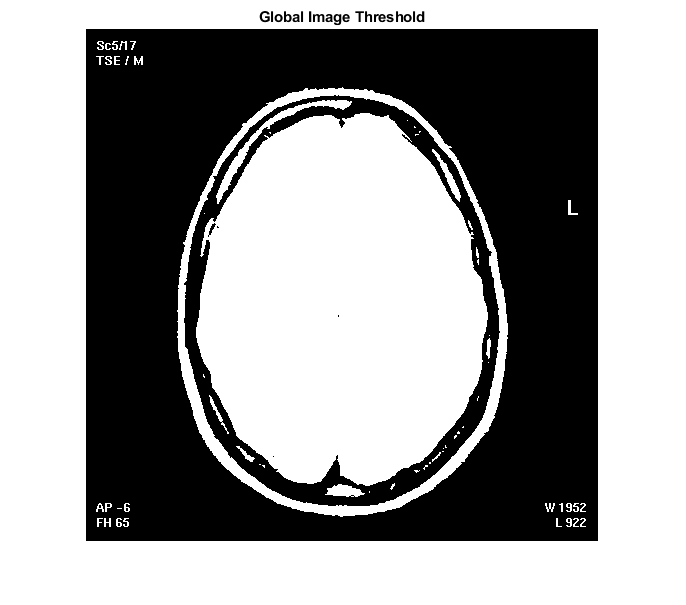

%level = 0.4941
%level = 0.5

%Convert the image into a binary image using the threshold.
BW = imbinarize(I,level);

%Display the original image next to the binary image.
imshow(BW);title('Global Image Threshold')

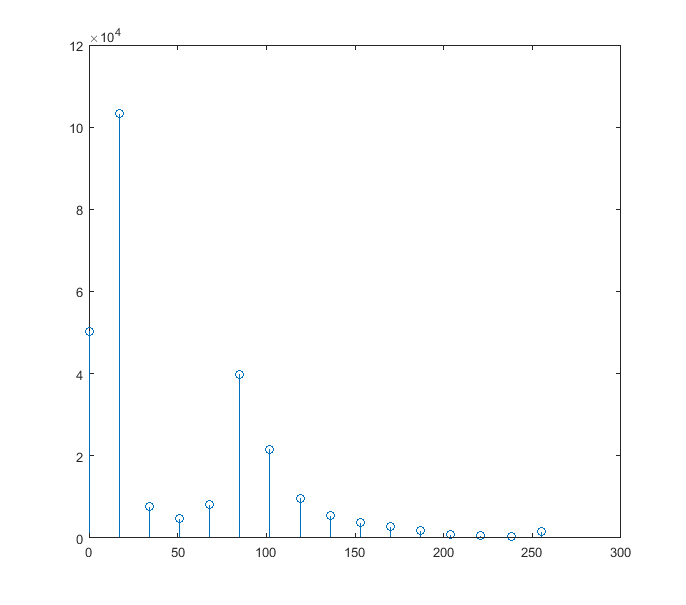

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Global Histogram Threshold
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Calculate a 16-bin histogram for the image.
[counts,x] = imhist(I,16);
stem(x,counts)

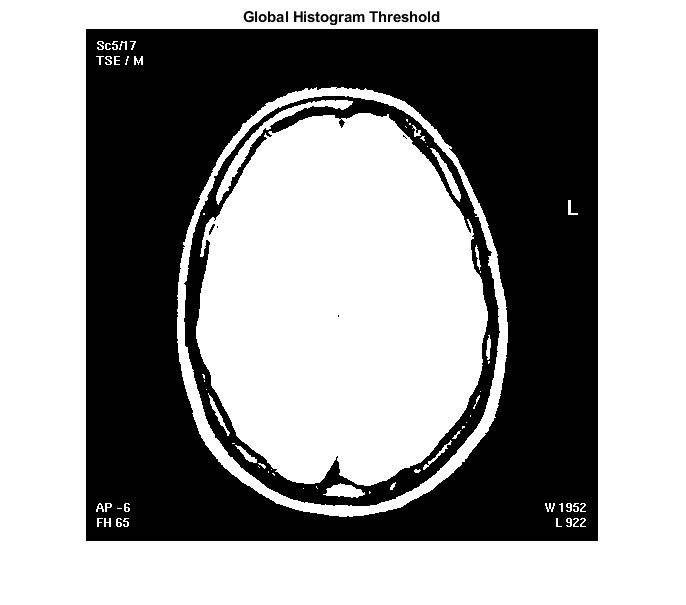


%Compute a global threshold using the histogram counts.
T = otsuthresh(counts);

%Create a binary image using the computed threshold and display the image.
BW = imbinarize(I,T);
figure
imshow(BW);title('Global Histogram Threshold')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Multi Level Thresholding using Otsu thresh
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Calculate two threshold levels.
thresh = multithresh(I,2);

%Segment the image into three levels using imquantize .
seg_I = imquantize(I,thresh);

%Convert segmented image into color image using label2rgb and display it.
% RGB = label2rgb(seg_I);
A = mat2gray(seg_I)

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

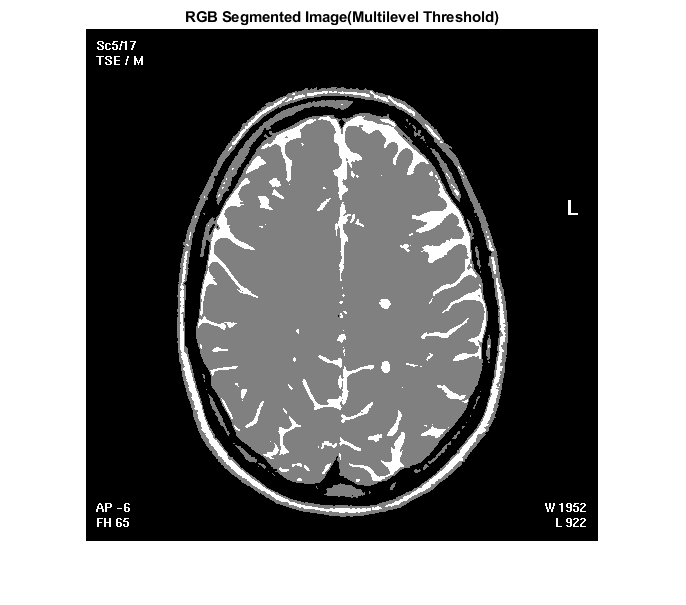

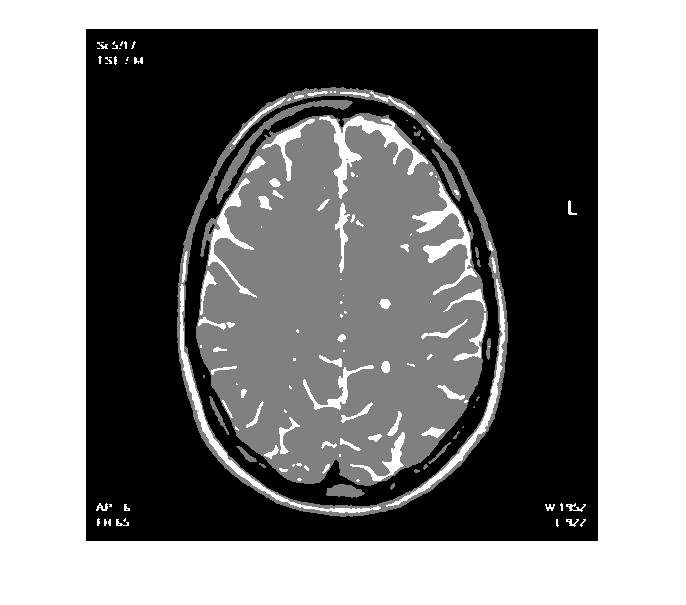

figure;
imshow(A)
axis off
title('RGB Segmented Image(Multilevel Threshold)')

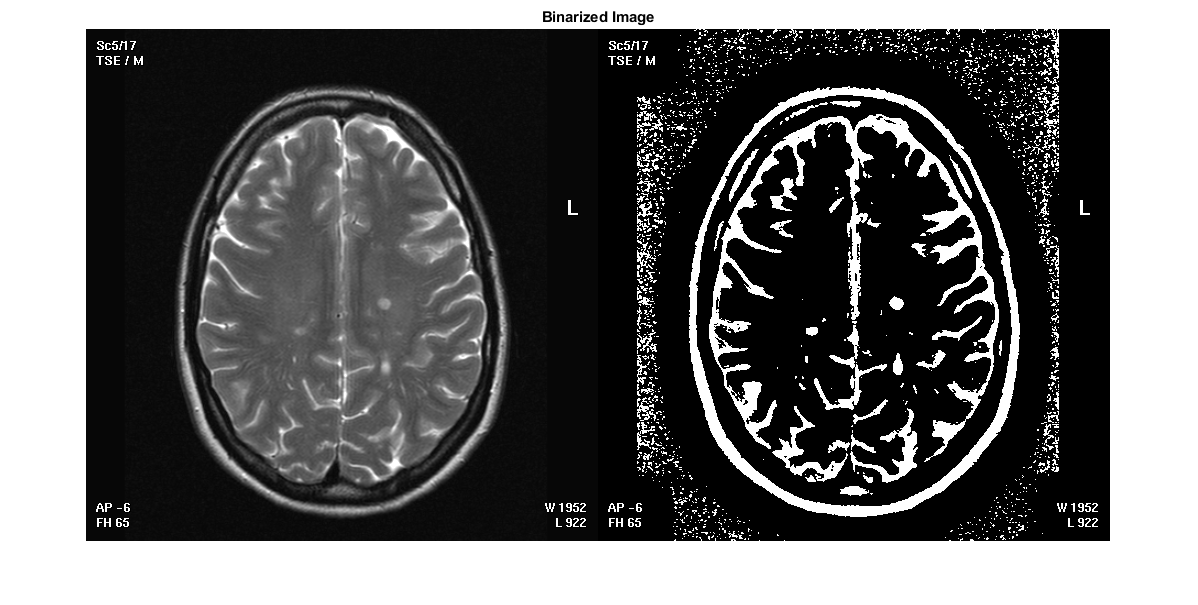

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Adaptive Thresholding
%%%%%%%%%%%%%%%%%%%%%%

%Use adaptthresh to determine threshold to use in binarization operation.
T = adaptthresh(I, 0.4);

%Convert image to binary image, specifying the threshold value.
BW = imbinarize(I,T);

%Display the original image with the binary version, side-by-side.
figure
imshowpair(I, BW, 'montage');title('Binarized Image')

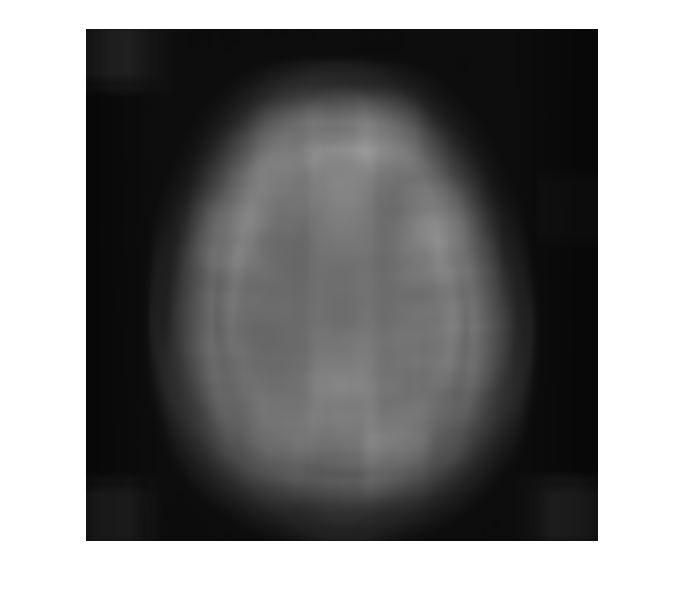


%Find Threshold and Segment Bright Texture from Dark Background
T = adaptthresh(I,0.4,'ForegroundPolarity','bright');
figure
imshow(T)

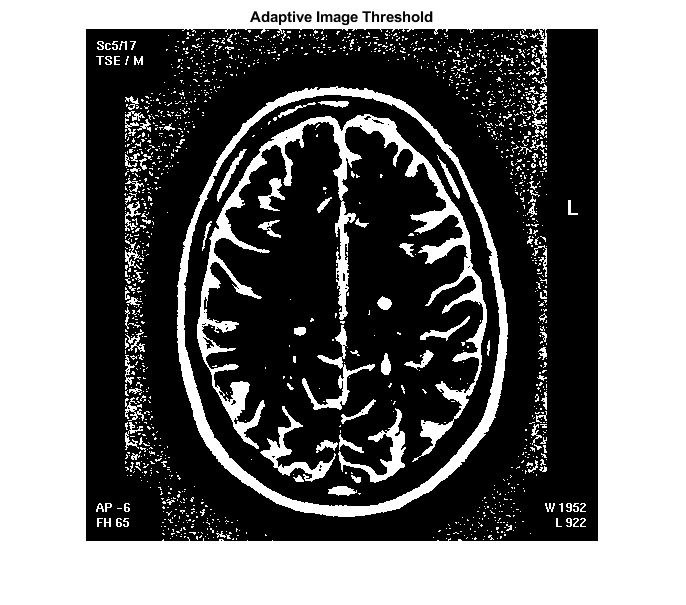

Error using imnoise
Expected input number 1, I, to be one of these types:

uint8, uint16, double, int16, single

Instead its type was logical.

Error in imnoise>ParseInputs (line 107)
validateattributes(a, {'uint8','uint16','double','int16','single'}, {}, mfilename, ...

Error in imnoise (line 86)



%Binarize image using locally adaptive threshold
BW = imbinarize(I,T);
figure
imshow(BW);title('Adaptive Image Threshold')

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% [centers, radii, metric] = imfindcircles(BW,[11 21]);
% Retain the five strongest circles according to the metric values.
% 
% centersStrong5 = centers(1:1,:); 
% radiiStrong5 = radii(1:1);
% metricStrong5 = metric(1:1);
% Draw the five strongest circle perimeters over the original image.
% 
% viscircles(centersStrong5, radiiStrong5,'EdgeColor','b');
